## **Вариант 8**

## **Задание 1. Одноканальная система в форме вход-выход**

a2 = 9;
a1 = 26;
a0 = 24;
b2 = 2;
b1 = 6;
b0 = 8;

mdl = "task1";
open_system(mdl);

simIn = Simulink.SimulationInput(mdl);

out1 = sim(simIn);

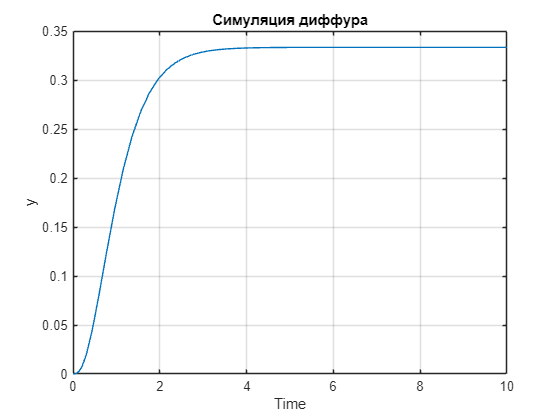

res = get(out1, "yout");
y = res{2};
plot(y.Values.Time, y.Values.Data)
grid on
xlabel("Time")
ylabel("y")
title("Симуляция диффура")

## Задание 2. Переход от формы вход-выход к форме вход-состояние-выход

mdl = "task1_ctrl";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);
out2 = sim(simIn);

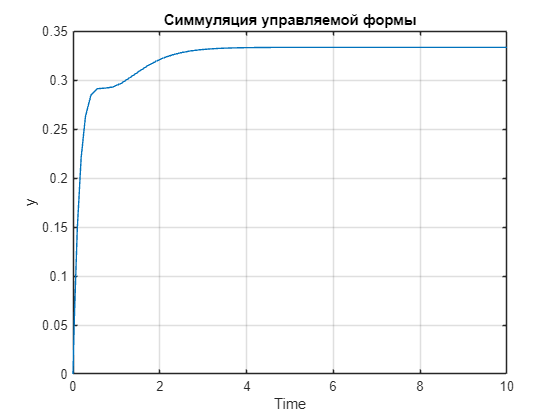

res = get(out2, "yout");
y = res{1};
plot(y.Values.Time, y.Values.Data)
grid on
xlabel("Time")
ylabel("y")
title("Симмуляция управляемой формы")

mdl = "task1_wtch";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);
out3 = sim(simIn);

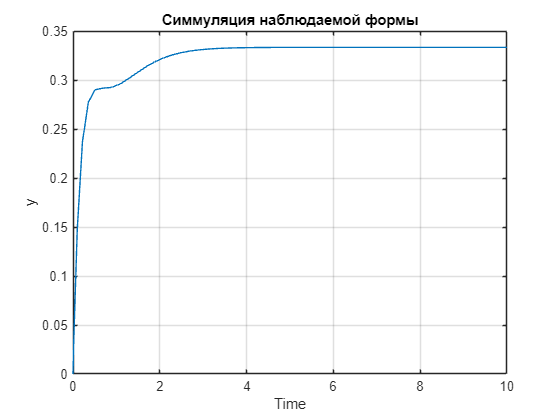

res = get(out3, "yout");
y = res{1};
plot(y.Values.Time, y.Values.Data)
grid on
xlabel("Time")
ylabel("y")
title("Симмуляция наблюдаемой формы")

mdl = "task1_diag";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);
out4 = sim(simIn);

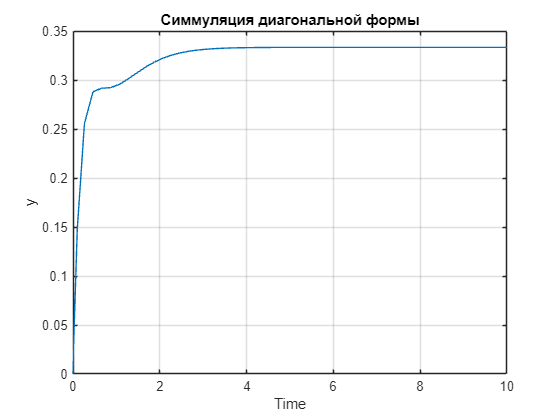

res = get(out4, "yout");
y = res{1};
plot(y.Values.Time, y.Values.Data)
grid on
xlabel("Time")
ylabel("y")
title("Симмуляция диагональной формы")